X = (-3:0.2:3)';
Y = sinc(X) + 0.1.*randn(length(X),1);


Xtrain = X(1:2:end);
Ytrain = Y(1:2:end);
Xtest = X(2:2:end);
Ytest = Y(2:2:end);



% gam = 1e6;
% sig2 = 1;
% type = 'function estimation';
% [alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});

% 
% Yt = simlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b},Xtest);
% 

% plotlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b});
% 
% 
% hold on; plot(min(X):.1:max(X),sinc(min(X):.1:max(X)),'r-.');
% 
% MSE = mean((Yt - Ytest).^2)   % Mean Squared Error
% disp(MSE)





% gamlist = [1e-2 1e-1 1  1e1 1e2 1e3 1e6];
% sig2list = [1e-4 1e-2 1 1e2 1e4];
% 
% MSElist = zeros(length(gamlist),length(sig2list));
% 
% for i=1:length(gamlist)
%     for j=1:length(sig2list)
%         gam = gamlist(i);
%         sig2 = sig2list(j);
%         type = 'function estimation';
%         [alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});
%         
%         Yt = simlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b},Xtest);
%         
%         MSElist(i,j) = mean((Yt - Ytest).^2);   % Mean Squared Error
%         
%     end
% end
% 

% cdata = MSElist;
% yvalues = gamlist;
% xvalues = sig2list;
% h = heatmap(xvalues,yvalues,cdata);
% 
% h.Title = 'MSE Results ';
% h.XLabel = 'Sig2';
% h.YLabel = 'Gam';

type = 'f';
kernel_type = 'RBF_kernel';

model = {Xtrain,Ytrain,type,[],[],kernel_type};


[gam,sig2] = tunelssvm(model,'gridsearch','leaveoneoutlssvm', {'mse'});


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         214.4776
                                          [sig2]        0.099168
                                          F(X)=         0.0080143
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  leaveoneoutlssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   10.6782   0.00814019
    cost of starting values:           0.1157
    time needed for 1 evaluation (sec):0
    limits of the grid:   [gam]         10.6782119       31831.301
                          [sig2]        0.0081402      1.2081
 
OPTIMIZATION IN LOG SCALE...


grain = 7

FIRST ITERATION:
   X=5.0349     -2.3109 ,F(X)=0.0083975;
ITERATION: 2
  dF=0.00045219, dX=0.9528, X=5.9802     -2.1921 ,F(X)=0.0079453;
Obtained hyper-parameters: [gamma sig2]: 395.5326     0.1116769



[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});
        
Yt = simlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b},Xtest);

plotlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b});

Start Plotting...

finished


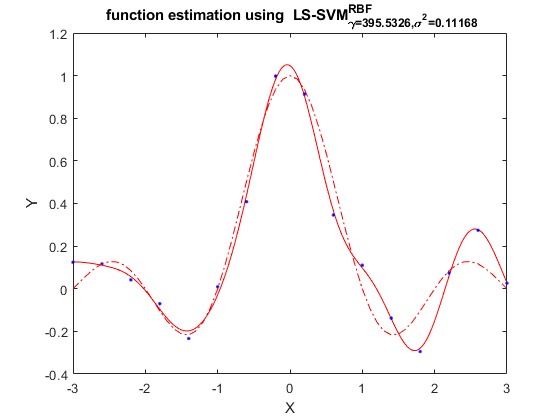



hold on; plot(min(X):.1:max(X),sinc(min(X):.1:max(X)),'r-.');

        
MSE = mean((Yt - Ytest).^2);   % Mean Squared Error
disp(gam);

  395.5326



disp(sig2);

    0.1117



disp(MSE);

    0.0176

